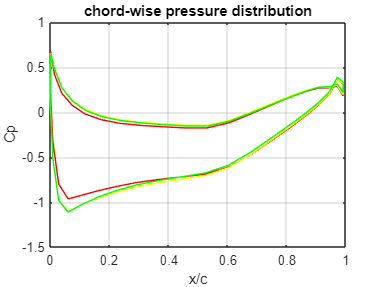

clear
clc

% read and plot chord-wise pressure distribution 
Cp1= fopen('sect_001'); 
data1 = textscan(Cp1, '%f %f');
fclose(Cp1);

Cp2 = fopen('sect_002'); 
data2 = textscan(Cp2, '%f %f'); 
fclose(Cp2);

Cp3 = fopen('sect_003');
data3 = textscan(Cp3, '%f %f'); 
fclose(Cp3);

x1 = data1{1}; 
y1 = data1{2};

x2 = data2{1}; 
y2 = data2{2};

x3 = data3{1}; 
y3 = data3{2};

figure
plot(x1, y1,"r")
hold on
plot(x2,y2,"y")
plot(x3,y3,"g")
xlabel('x/c'); 
ylabel('Cp'); 
title('chord-wise pressure distribution'); 
grid on
hold off

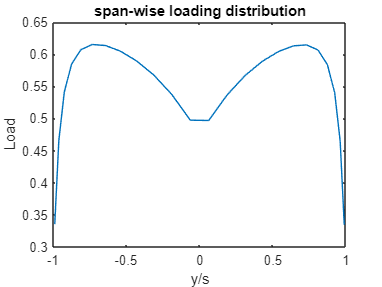


% read and plot span-wise loading distribution
L1= fopen('span_load'); 
data4 = textscan(L1, '%f %f');
fclose(L1);

x4 = data4{1};
y4 = data4{2};

figure
plot(x4, y4)
xlabel('y/s'); 
ylabel('Load'); 
title('span-wise loading distribution'); 